# **Script for rectification**

This is a simple way to make the rectification based on the survey made on December 2021 by Adelaide.

Since, we cannot obtain the camera parameters, a simple regresion is done.

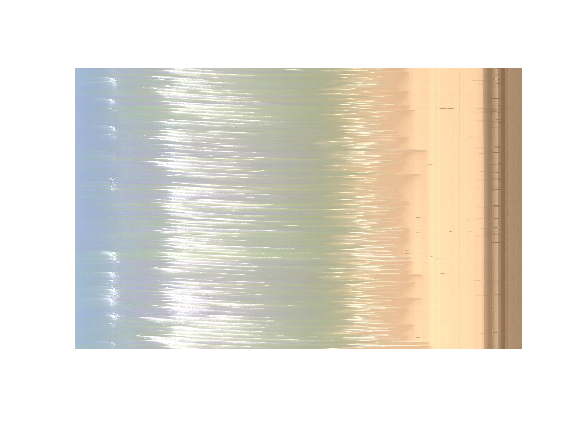

% Corresponds to "0_Calcul_dist_pixels_cross_shore" file
% G = load('D:\CAMERA\ESPODZA\Camera_Toolbox\extract_bathy_v5\0_Calcul_dist_pixels_cross_shore\dx_stack_cross_GPP.mat');
%-- Constants
H_camera         = 18.888;             % Camera height [m]
sk1              =  [2500 1];       % St Louis chosen transect
sk2              =  [1250 4300];
% R_terre          =  6371000;        % Earth radius [m]
% dist_horizon     =  sqrt(2*H_camera*R_terre + H_camera^2);

%-- Path to data
path_to_data     =  '/MATLAB Drive/Senegal/Timestacks/Timestacks_15min/';
stacked_image    =  [path_to_data,'S_3_202104161000.jpg'];
I                =  imread(stacked_image);
figure
imshow(I)

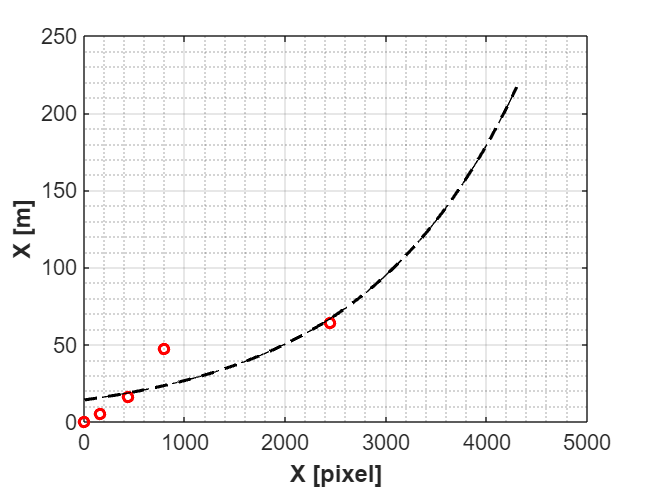

%-- Data fit (exponential)

rect_pxl         = [0, 160, 442, 797, 2449];% Points

% rect_pxl         = [0, 160, 442, 797, 2449, 3269];% Points
dx               =  1:size(I,2);      % Distance in p used for rectification [pxl]
rect_m           =  [0, 5.552, 16.56803638, 47.72050534, 64.55324724]; % Points used for rectification [m]ixels from shore to offshore
% rect_m           =  [338486.996, 338481.444, 338470.490, 338439.361, 338422.721]; % Points used for rectification [m]ixels from shore to offshore
fit_horizon      =  fittype('exp1');  % Fitting model
f                =  fit(rect_pxl',rect_m',fit_horizon);
dxXX             =  f(dx);            % Distance in meters from shore to offshore
save(strcat('/MATLAB Drive/Senegal/Output/rect_Jennifer'))

% figure(3);
% plot(f,);
figure(1);
plot(dxXX,'--k', 'linewidth',2);
hold on
plot(rect_pxl, rect_m, 'or', 'linewidth',2)
% plot(G.dxXX,'--r', 'linewidth',2);
grid on; grid minor

figure(1);
plot(dx,dxXX,'--k');
grid on; set(gca,'fontsize',14);
xlabel('X [pixel]','fontweight','bold');
ylabel('X [m]','fontweight','bold');

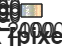

% axis([1 size(I,2) 0 dist_horizon]);

figure(2);
subplot(211);
imshow(I); axis on;
set(gca,'fontsize',14);
xlabel('X [pixel]','fontweight','bold');
ylabel('Time','fontweight','bold');

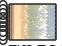

% subplot(212);
% figure(3)
% imshow(I); axis on;
% 
% % set(gca,'XTick',([1e3 2e3 3e3 4e3]), 'XDir', 'reverse');
% % set(gca,'XTickLabel',{num2str(dxXX(4e3)),num2str(dxXX(3e3)),num2str(dxXX(2e3)),num2str(dxXX(1e3))});
% 
% % set(gca,'XTickLabel',{'0',num2str(dxXX(1e3)),num2str(dxXX(2e3)),num2str(dxXX(3e3)),num2str(dxXX(4e3))});
% 
% set(gca,'fontsize',14);
% xlabel('X [m]','fontweight','bold');
% ylabel('Time','fontweight','bold');

figure
image(flipud(dxXX),[1:size(I,2)],I); axis on;

% set(gca,'XDir', 'reverse');
% set(gca,'XTickLabel',{num2str(dxXX(4e3)),num2str(dxXX(3e3)),num2str(dxXX(2e3)),num2str(dxXX(1e3))});
% 
% % set(gca,'XTickLabel',{'0',num2str(dxXX(1e3)),num2str(dxXX(2e3)),num2str(dxXX(3e3)),num2str(dxXX(4e3))});

set(gca,'fontsize',14);
xlabel('X [m]','fontweight','bold');
ylabel('Time','fontweight','bold');